# **Reparameterized Gompertz models with triplicates**

**Loyal Murphy - January 19, 2024**

Using this code, I'll be able to apply the Gompertz model to each system and be able to use the final values.

### **Initialization**

clear variables
clc
clf

# **DATA EXTRACTION**

### Extract Methanotroph Data

scans = dir('*.mat');

all_meth_OD = {};
ms = 0; %Initialize counter

for i = 1:length(scans)
    clear n
    n = scans(i).name;
    if startsWith(n,'M')
        ms = ms + 1;
        meth_data = load(n);
        if length(fieldnames(meth_data)) == 3
            j = fieldnames(meth_data);
            data = meth_data.(j{1});
            factor = meth_data.(j{2});
            to = meth_data.(j{3});
            
            %Get the OD values (multiplying by the factor)
            for x = 1:size(data,1)
                odValues(x) = data{x,1}.Abs(data{x,1}.nm == 600);
            end
            all_meth_OD{ms,1} = reshape(odValues,[size(data,1)/3,3]).*factor';
            if ms == 3
                all_meth_OD{ms,1}(13,2) = 5.46;
            end
            %Get the times
            pts = size(data,1)/3;
            time_matrix = zeros(pts,1); %Initialize time_matrix
            for k = 1:pts
                time_matrix(k) = hours(mean([data{k,2},...
                    data{k+pts,2},...
                    data{k+2*pts,2}]) - to);
            end
            all_meth_OD{ms,2} = time_matrix;

        elseif length(fieldnames(meth_data)) == 2
            j = fieldnames(meth_data);
            
            %Get the OD values (factor already multiplied)
            all_meth_OD{ms,1} = meth_data.(j{1});
            
            %Get the time values (initial time already subtracted)
            all_meth_OD{ms,2} = meth_data.(j{2});
        end

    clear data factor to odValues j k x meth_data pts
    end
end
clear n ms time_matrix i

%Formatting modifications:
all_meth_OD{4,2} = transpose(all_meth_OD{4,2}); %LW14T times
all_meth_OD{6,2} = transpose(all_meth_OD{6,2}); %Quisquiliarum times

%Transforming into gDCW
all_meth_gDCW = cell(7,2);
gDCW_conversion = [0.235,0.369,0.382,0.659,0.460,0.4,0.447];
for j = 1:size(all_meth_OD,1)
    all_meth_gDCW{j,1} = all_meth_OD{j,1}*gDCW_conversion(j); %OD v. gDCW
    all_meth_gDCW{j,2} = all_meth_OD{j,2}; %Times are the same
end

clear gDCW_conversion all_meth_OD

### Extract Microalgae Data

scans = dir('*.mat');

all_photo_gDCW = {};
ms = 0; %Initialize counter

for i = 1:length(scans)
    clear n
    n = scans(i).name;
    if startsWith(n,'P')
        ms = ms + 1;
        photo_data = load(n);
        if length(fieldnames(photo_data)) == 3
            j = fieldnames(photo_data);
            data = photo_data.(j{1});
            factor = photo_data.(j{2});
            to = photo_data.(j{3}); 
            
            %Get the OD values (multiplying by the factor)
            for x = 1:size(data,1)
                gDCWValues(x) = data{x,1}.Abs(data{x,1}.nm == 750);
            end
            all_photo_gDCW{ms,1} = reshape(gDCWValues,[size(data,1)/3,3]).*factor';
                            
            %Get the times
            pts = size(data,1)/3;
            time_matrix = zeros(pts,1); %Initialize time_matrix
            for k = 1:pts
                time_matrix(k) = hours(mean([data{k,2},...
                    data{k+pts,2},...
                    data{k+2*pts,2}]) - to);
            end
            all_photo_gDCW{ms,2} = time_matrix;

        elseif length(fieldnames(photo_data)) == 2
            j = fieldnames(photo_data);
            
            %Get the OD values (factor already multiplied)
            all_photo_gDCW{ms,1} = photo_data.(j{1});
            
            %Get the time values (initial time already subtracted)
            all_photo_gDCW{ms,2} = photo_data.(j{2});
        end

    clear data factor to gDCWValues j k x photo_data pts
    end
end

gDCW_conversion = [0.52,1,1,0.39,1]; %Dimorphus and Sorokiniana data are OD's!
for k = 1:5
    all_photo_gDCW{k,1} = all_photo_gDCW{k,1}*gDCW_conversion(k);
end
clear n ms time_matrix i gDCW_conversion k scans

# **PLOT GROWTH CURVES and 4Z FITTINGS**

### Methanotrophs

Meth_titles = ["Cap";"Fib";"LW13";"LW14T";"OB3b";"QQ";"S1"];
Colors = {[0.6 0 0],[0 0.5 0.5],[0 0 1],[0.5 0.5 1],[0.4 0.2 0.7],[0 0 0],[0.3 0.3 0]};
Inits = {[1.7,0.1,20],[1.3,0.1,15],[2.1,0.1,15],[0.5,0.1,5],[2.4,0.1,35],[1,0.01,50],[0.8,0.1,10]}; %Initials for ZM solver
Inits2 = {[0.15,1],[0.15,0],[0.15,1],[0.10,1],[0.10,10],[0.05,1],[0.15,1]}; %Initials for XM solver
% Make storage variables for later %
K_vals = zeros(3,length(Meth_titles));
muR_vals = zeros(3,length(Meth_titles));
tLAG_vals = zeros(3,length(Meth_titles));
mu_max_vals = zeros(3,length(Meth_titles));
mu_max_vals4 = zeros(3,length(Meth_titles));
mu_max_vals5 = zeros(3,length(Meth_titles));
td_vals = zeros(3,length(Meth_titles));
td_vals4 = zeros(3,length(Meth_titles));
td_vals5 = zeros(3,length(Meth_titles));
D_vals = zeros(3,length(Meth_titles));

for i = 1:length(Meth_titles)
%for i = 1:size(all_meth_gDCW,1)
    gDCWs = all_meth_gDCW{i,1};
    Times = all_meth_gDCW{i,2};    

    % Plot the individual data sets with their Gompertz models
    x = Times;
    for j = 1:3
        % Set up fitting parameters %
        Xo = gDCWs(1,j); %Initial biomass
        foB = fitoptions('Method','NonlinearLeastSquares','Lower',[0,0,0,0.025],'Upper',[3,0.35,100,0.1],'StartPoint',[Inits{i},Xo]);
        ft_ZMB = fittype('d + a*exp(-exp(exp(1)*b/a * (c - x) + 1))','independent',{'x'},'dependent',{'y'},'options',foB); %Zweitering
        % a = Carrying Capacity
        % b = Growth Rate
        % c = Lag Time
        % d = Vertical Shift

        % Gompertz Model Predictions %
        y = gDCWs(:,j);
        if i == 1
            x = x(1:13);
            y = y(1:13);
        end
        
        if i == 7
            x = x(1:11);
            y = y(1:11);
        end
        [curve_ZMB,sZMB] = fit(x,y,ft_ZMB);
        K_vals(j,i) = curve_ZMB.a;
        muR_vals(j,i) = curve_ZMB.b;
        tLAG_vals(j,i) = curve_ZMB.c;
        D_vals(j,i) = curve_ZMB.d;

        % Lastly, try using the piecewise model from 0 to Tlag
        tEXP5 = linspace(tLAG_vals(j,i)*0,tLAG_vals(j,i),51);
        fo5 = fitoptions('Method','NonlinearLeastSquares','Lower',[0,0,0],'Upper',[Xo*2,0.3,30],'StartPoint',[Xo,Inits2{i}]);
        ft_XMXo5 = fittype('expo(t,x1,x2,x3)','independent',{'t'},'options',fo5);
        [curve_XMXo5,sXMXo5] = fit(tEXP5',curve_ZMB(tEXP5),ft_XMXo5);
        mu_max_vals5(j,i) = curve_XMXo5.x2;
        td_vals5(j,i) = curve_XMXo5.x3;
        %Xo_vals5(j,i) = curve_XMXo5.x1;

    end

end

## **Plotting Methanotroph Monoculture Data**

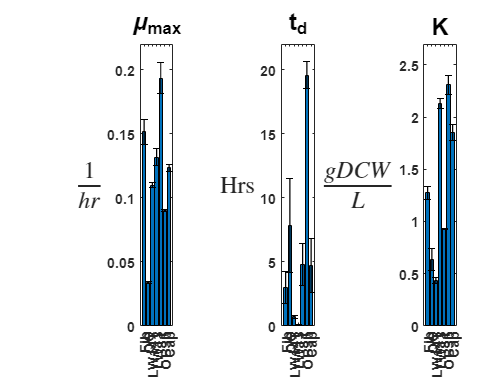

% Reorder code %%%%%%%%%%%%%%%%%%%
while ~strcmp(Meth_titles(1),'Fib') %Ensures reordering happens only once!
pub_idx = [2 6 4 3 7 5 1];
Meth_titles = Meth_titles(pub_idx);
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


figure(); clf;
subplot(1,3,3)
statDCW_vals = mean(K_vals) + mean(D_vals);
statDCW_std = std(K_vals);
hold on
bar(Meth_titles,statDCW_vals(pub_idx));
errorbar(statDCW_vals(pub_idx),statDCW_std(pub_idx),'LineStyle','none','Color','k','LineWidth',1);
hold off
set(gca,'FontSize',12,'FontWeight','bold');
ylabel('$\frac{gDCW}{L}$','Interpreter','latex','FontSize',20,'FontWeight','bold','Rotation',0);
ylim([0,2.7]);
yticks([0 0.5 1 1.5 2 2.5]);
title('K','FontSize',20,'FontWeight','bold');
box on;

je = gca;

subplot(1,3,1)
mu_max_ave = mean(mu_max_vals5);
mu_max_std = std(mu_max_vals5);
hold on
bar(Meth_titles,mu_max_ave(pub_idx));
errorbar(mu_max_ave(pub_idx),mu_max_std(pub_idx),'LineStyle','none','Color','k','LineWidth',1);
hold off
set(gca,'FontSize',12,'FontWeight','bold');
title('\mu_{max}','FontSize',20,'FontWeight','bold')
ylabel('$\frac{1}{hr}$','Interpreter','latex','FontSize',20,'FontWeight','bold','Rotation',0);
ylim([0,0.22]);
yticks([0 0.05 0.10 0.15 0.2 0.25])
box on;

jc = gca;

subplot(1,3,2)
hold on
td_ave = mean(td_vals5);
td_std = std(td_vals5);
bar(Meth_titles,td_ave(pub_idx));
errorbar(td_ave(pub_idx),td_std(pub_idx),'LineStyle','none','Color','k','LineWidth',1);
hold off
set(gca,'FontSize',12,'FontWeight','bold');
title('t_d','FontSize',20,'FontWeight','bold')
ylabel('Hrs','Interpreter','latex','FontSize',20,'FontWeight','bold','Rotation',0);
ylim([0,22]);
yticks([0 5 10 15 20]);
box on;


jd = gca;

## Methanotroph Average Models

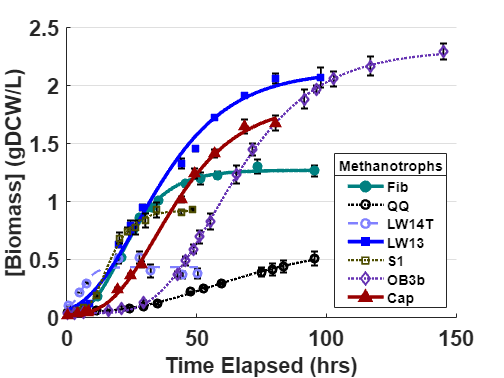

Meth_titles = ["Cap";"Fib";"LW13";"LW14T";"OB3b";"QQ";"S1"];
Colors = {[0.6 0 0],[0 0.5 0.5],[0 0 1],[0.5 0.5 1],[0.4 0.2 0.7],[0 0 0],[0.3 0.3 0]};
Inits = {[1.7,0.1,20],[1.3,0.1,15],[2.1,0.1,15],[0.5,0.1,5],[2.4,0.1,35],[1,0.01,50],[0.8,0.1,10]}; %Initials for ZM solver
Marks = ['^';'o';'s';'o';'d';'o';'s'];
LineStys = ["-";"-";"-";"--";":";":";":"];
LineW = [3;3;3;2;2;2;2];
MarkFill = {[0.6 0 0];[0 0.5 0.5];[0 0 1];"none";"none";"none";"none"};

figure(); clf; %Start a new plot
%All the code below is to plot the Gompertz fits onto monoculture data
for i = pub_idx
    gDCWs = all_meth_gDCW{i,1};
    Times = all_meth_gDCW{i,2}; 
    xAve = mean(gDCWs,2);
    xstd = std(gDCWs,[],2);

    Xo = gDCWs(1); %Initial biomass
    foB = fitoptions('Method','NonlinearLeastSquares','Lower',[0,0,0,Xo*0.8],'Upper',[3,0.35,100,Xo*1.2],'StartPoint',[Inits{i},Xo]);
    ft_ZMB = fittype('d + a*exp(-exp(exp(1)*b/a * (c - x) + 1))','independent',{'x'},'dependent',{'y'},'options',foB); %Zwietering
    if i == 1 %To forgo the last point of Capsulatus
            Times = Times(1:13);
            xAve = xAve(1:13);
            xstd = xstd(1:13);
    end
    
    if i == 7 %To avoid elongated stationary phase from S1
            Times = Times(1:11);
            xAve = xAve(1:11);
            xstd = xstd(1:11);
    end
    [curve_ZMB,sZMB] = fit(Times,xAve,ft_ZMB);
    tSpace = linspace(0,max(Times),301);

    %Plot the Data, Error Bars, and Model in order.
    hold on
    errorbar(Times,xAve,xstd,'k','LineStyle','none','LineWidth',1.5);
    plot(Times,xAve,'Marker',Marks(i),'Color',Colors{i},'MarkerFaceColor',MarkFill{i},'MarkerSize',6,'LineStyle','none','LineWidth',2.3);
    plot(tSpace,curve_ZMB(tSpace),'LineStyle',LineStys(i),'Color',Colors{i},'LineWidth',LineW(i));
    plot(nan,nan,'Marker',Marks(i),'Color',Colors{i},'MarkerFaceColor',MarkFill{i},'MarkerSize',7,'LineStyle',LineStys(i),'LineWidth',LineW(i)); %Legend
    hold off
end
ax = gca;
ax.FontSize = 18;
ax.FontWeight = 'bold';
xlabel('Time Elapsed (hrs)','FontSize',18,'FontWeight','bold');
ylabel('[Biomass] (gDCW/L)','FontSize',18,'FontWeight','bold');
lgd = legend('','','','Fib','','','','QQ','','','','LW14T','','','','LW13','','','','S1','','','','OB3b','','','','Cap','FontSize',12,'location','southeast');
title(lgd,'Methanotrophs')
ax.YGrid = 'on';


jab = gca;

# **Microalgae Monoculture Data**

Photo_titles = ["Dim";"Kess";"Obli";"Soro";"Vulg"];
Colors = {[0.6 0 0],[0 0.5 0.5],[0 0 1],[0.5 0.5 1],[0.4 0.2 0.7]};
Inits = {[1.7,0.1,0],[2.2,0.05,2],[2.3,0.1,2],[2.4,0.1,2],[3,0.05,10]}; %Initials for solver!
Inits2 = {[0.15,5],[0.15,5],[0.15,5],[0.15,5],[0.15,5]};

% Make storage variables for later %
K_vals = zeros(3,length(Photo_titles));
D_vals = zeros(3,length(Photo_titles));
muR_vals = zeros(3,length(Photo_titles));
tLAG_vals = zeros(3,length(Photo_titles));
mu_max_vals = zeros(3,length(Photo_titles));
mu_max_vals3 = zeros(3,length(Photo_titles));
mu_max_vals4 = zeros(3,length(Photo_titles));
mu_max_vals5 = zeros(3,length(Photo_titles));
td_vals = zeros(3,length(Photo_titles));
td_vals4 = zeros(3,length(Photo_titles));
td_vals5 = zeros(3,length(Photo_titles));
Xo_vals4 = zeros(3,length(Photo_titles));

for i = 1:size(all_photo_gDCW,1)
%for i = 4 %Sorokiniana
    gDCWs = all_photo_gDCW{i,1};
    Times = all_photo_gDCW{i,2};
    
    % Plot the individual data sets with their Gompertz models
    x = Times;
    for j = 1:3
        % Set up fitting parameters %
        Xo = gDCWs(1,j); %Initial biomass
        foB = fitoptions('Method','NonlinearLeastSquares','Lower',[0,0,0,0.025],'Upper',[3,0.35,100,0.050],'StartPoint',[Inits{i},Xo]);
        ft_ZMB = fittype('d + a*exp(-exp(exp(1)*b/a * (c - x) + 1))','independent',{'x'},'dependent',{'y'},'options',foB); %Zweitering
        % a = Carrying Capacity
        % b = Growth Rate
        % c = Delay Time
        % d = Vertical Shift

        % Define gDCW measurements and model predictions
        y = gDCWs(:,j);
        [curve_ZMB,sZMB] = fit(x,y,ft_ZMB);
        K_vals(j,i) = curve_ZMB.a;
        muR_vals(j,i) = curve_ZMB.b;
        tLAG_vals(j,i) = curve_ZMB.c;
        D_vals(j,i) = curve_ZMB.d;

        % Lastly, try using the piecewise model from 0 to Tlag
        tEXP5 = linspace(0,tLAG_vals(j,i),50);
        fo5 = fitoptions('Method','NonlinearLeastSquares','Lower',[0,0,0],'Upper',[Xo*2,0.3,30],'StartPoint',[Xo,Inits2{i}]);
        ft_XMXo5 = fittype('expo(t,x1,x2,x3)','independent',{'t'},'options',fo5);
        [curve_XMXo5,sXMXo5] = fit(tEXP5',curve_ZMB(tEXP5),ft_XMXo5);
        mu_max_vals5(j,i) = curve_XMXo5.x2;
        td_vals5(j,i) = curve_XMXo5.x3;
        %Xo_vals5(j,i) = curve_XMXo5.x1;

    end

end

## **Plotting Microalgae Monoculture Data**

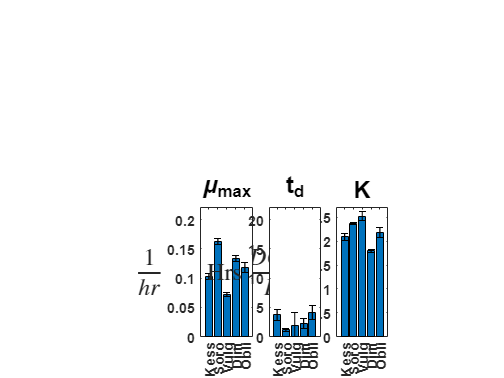

% Reorder code %%%%%%%%%%%%%%%%%%%
while ~strcmp(Photo_titles(1),'Kess') %Ensures reordering happens only once!
pub_idx = [2 4 5 1 3];
Photo_titles = Photo_titles(pub_idx);
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

f123 = figure(123); clf;
subplot(2,6,11)
statDCW_vals = mean(K_vals) + mean(D_vals);
statDCW_std = std(K_vals);
hold on
bar(Photo_titles,statDCW_vals(pub_idx));
errorbar(statDCW_vals(pub_idx),statDCW_std(pub_idx),'LineStyle','none','Color','k','LineWidth',1);
hold off
set(gca,'FontSize',12,'FontWeight','bold');
ylabel('$\frac{gDCW}{L}$','Interpreter','latex','FontSize',20,'FontWeight','bold','Rotation',0);
ylim([0,2.7]);
yticks([0 0.5 1 1.5 2 2.5]);
title('K','FontSize',20,'FontWeight','bold');
box on;

subplot(2,6,9)
mu_max_ave = mean(mu_max_vals5);
mu_max_std = std(mu_max_vals5);
hold on
bar(Photo_titles,mu_max_ave(pub_idx));
errorbar(mu_max_ave(pub_idx),mu_max_std(pub_idx),'LineStyle','none','Color','k','LineWidth',1);
hold off
set(gca,'FontSize',12,'FontWeight','bold');
title('\mu_{max}','FontSize',20,'FontWeight','bold')
ylabel('$\frac{1}{hr}$','Interpreter','latex','FontSize',20,'FontWeight','bold','Rotation',0);
ylim([0,0.22]);
yticks([0 0.05 0.10 0.15 0.2]);
box on;

subplot(2,6,10)
hold on
td_ave = mean(td_vals5);
td_std = std(td_vals5);
bar(Photo_titles,td_ave(pub_idx));
errorbar(td_ave(pub_idx),td_std(pub_idx),'LineStyle','none','Color','k','LineWidth',1);
hold off
set(gca,'FontSize',12,'FontWeight','bold');
title('t_d','FontSize',20,'FontWeight','bold')
ylabel('Hrs','Interpreter','latex','FontSize',20,'FontWeight','bold','Rotation',0);
ylim([0,22]);
yticks([0 5 10 15 20]);
box on;

## Microalgae Average Models

Photo_titles = ["Dim";"Kess";"Obli";"Soro";"Vulg"];
Colors = {[0.6 0 0],[0 0.5 0.5],[0 0 1],[0.5 0.5 1],[0.4 0.2 0.7]};
Inits = {[1.7,0.1,0],[2.2,0.05,2],[2.3,0.1,2],[2.4,0.1,2],[3,0.05,10]}; %Initials for solver!
Marks = ['o';'s';'o';'s';'s'];
LineStys = ["-";":";":";"-";"--"];
LineW = [3;2;2;3;2];
MarkFill = {[0.6 0 0];"none";"none";[0.5 0.5 1];"none"};

%figure(); clf; %Start a new plot
subplot(2,3,4);
%All the code below is to plot the Gompertz fits onto monoculture data
for i = pub_idx
    gDCWs = all_photo_gDCW{i,1};
    Times = all_photo_gDCW{i,2}; 
    xAve = mean(gDCWs,2);
    xstd = std(gDCWs,[],2);

    Xo = gDCWs(1); %Initial biomass
    foB = fitoptions('Method','NonlinearLeastSquares','Lower',[0,0,0,0.025],'Upper',[3,0.35,100,0.050],'StartPoint',[Inits{i},Xo]);
    ft_ZMB = fittype('d + a*exp(-exp(exp(1)*b/a * (c - x) + 1))','independent',{'x'},'dependent',{'y'},'options',foB); %Zweitering

    [curve_ZMB,sZMB] = fit(Times,xAve,ft_ZMB);
    tSpace = linspace(0,max(Times),301);

    %Plot the Data, Error Bars, and Model in order.
    hold on
    errorbar(Times,xAve,xstd,'k','LineStyle','none','LineWidth',1.5);
    plot(Times,xAve,'Marker',Marks(i),'Color',Colors{i},'MarkerFaceColor',MarkFill{i},'MarkerSize',6,'LineStyle','none','LineWidth',2.3);
    plot(tSpace,curve_ZMB(tSpace),'LineStyle',LineStys(i),'Color',Colors{i},'LineWidth',LineW(i));
    plot(nan,nan,'Marker',Marks(i),'Color',Colors{i},'MarkerFaceColor',MarkFill{i},'MarkerSize',7,'LineStyle',LineStys(i),'LineWidth',LineW(i)); %Legend
    hold off
end
ax = gca;
ax.FontSize = 18;
ax.FontWeight = 'bold';
xlabel('Time Elapsed (hrs)','FontSize',18,'FontWeight','bold');
ylabel('[Biomass] (gDCW/L)','FontSize',18,'FontWeight','bold');
lgd = legend('','','','Kess','','','','Soro','','','','Vulg','','','','Dim','','','','Obli','FontSize',12,'location','southeast');
title(lgd,'Microalgae')
ax.YGrid = 'on';
box on;

subplot(2,3,1,copyobj(jab,f123));

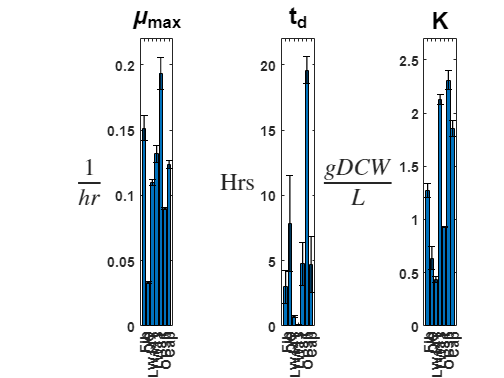

lgd = legend('','','','Fib','','','','QQ','','','','LW14T','','','','LW13','','','','S1','','','','OB3b','','','','Cap','FontSize',12,'location','southeast');
title(lgd,'Methanotrophs')
box on;
subplot(2,6,3,copyobj(jc,f123));
ax = gca;
ax.Title.FontSize = 20;
ax.YLabel.FontSize = 18;
subplot(2,6,4,copyobj(jd,f123));
ax = gca;
ax.Title.FontSize = 20;
ax.YLabel.FontSize = 18;
subplot(2,6,5,copyobj(je,f123));

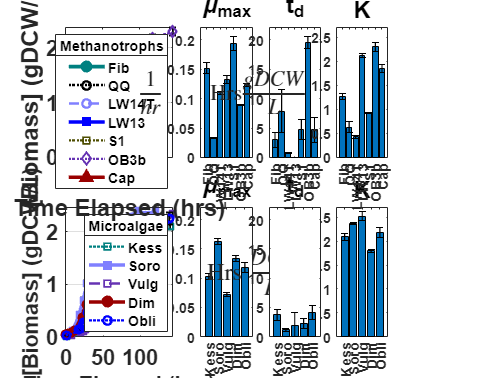

ax = gca;
ax.Title.FontSize = 20;
ax.YLabel.FontSize = 18;